
clc;clear all;close all
%% N=5;A=[0 1;-3 -5];B=[0;1];C=[1 0];D=[0]
%% Ts=0.2;   %tf=1  Qy,R   %yrefk=1;    %(y-yref)'*Qy*(y-yref)+u'Ru
N=15;
Ts=0.1;

A=[-13.8170 0 -0.205 0;
12.7753 -1.0417 0.205 0;
11.1784 0 -2.8154 1.7914;
0 0 3.0811 -3.8311];
B=[0.3083 0;-0.3083 0;-0.0542 0;0 -1.5375];
C=[0 1 0 0;0 0 1 0];D=zeros(2);

nx=size(A,1);
nu=size(B,2);


%Fcosto  Qbig, q
Qy=diag([100;1000]);
Qf=1000*Qy;
R=0.001*diag([1;1]);
C'*Qy*C

ans =            0           0           0           0
           0         100           0           0
           0           0        1000           0
           0           0           0           0


dC=diag(C'*Qy*C)

dC =            0
         100
        1000
           0


%Qbig=diag([dC;dC;dC;dC;dC])

Qbig=blkdiag(kron(eye(N),C'*Qy*C),kron(eye(N),R))

Qbig = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

Qbig(nx*(N-1)+(1:nx),nx*(N-1)+(1:nx))=C'*Qy*C+C'*Qf*C

Qbig = 1.0e+06 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

yrefk=[1;1];

ze_q=zeros(nu,1);

q=[];
for k=1:N
    %yrefk puede cambiar con k
    q=[q;-C'*Qy*yrefk];
end
q(nx*(N-1)+(1:nx),1)=-C'*Qy*yrefk-C'*Qf*yrefk;
for k=1:N
    q=[q;ze_q];
end
q

q =            0
        -100
       -1000
           0
           0
        -100
       -1000
           0
           0
        -100


id=eye(nx);
ze=zeros(nx);
zeB=0*B;
Gz=c2d(ss(A,B,C,D),Ts,'zoh')

Gz =
 
  A = 
               x1          x2          x3          x4
   x1      0.2468           0   -0.009454  -0.0009592
   x2      0.6542      0.9011    0.009454   0.0009592
   x3      0.5155           0      0.7686      0.1293
   x4     0.08996           0      0.2225      0.7013
 
  B = 
              u1         u2
   x1    0.01669    5.8e-05
   x2   -0.01669   -5.8e-05
   x3   0.005607    -0.0111
   x4  0.0004176    -0.1288
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


Gss=ss(Gz)

Gss =
 
  A = 
               x1          x2          x3          x4
   x1      0.2468           0   -0.009454  -0.0009592
   x2      0.6542      0.9011    0.009454   0.0009592
   x3      0.5155           0      0.7686      0.1293
   x4     0.08996           0      0.2225      0.7013
 
  B = 
              u1         u2
   x1    0.01669    5.8e-05
   x2   -0.01669   -5.8e-05
   x3   0.005607    -0.0111
   x4  0.0004176    -0.1288
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


Ad=Gss.A;
Bd=Gss.B;

## Sin restricciones


Aeq=zeros(N*nx,N*(nx+nu));
for k=1:N
    Aeq(nx*(k-1)+(1:nx),nx*(k-1)+(1:nx))=-id;
end
for k=2:N
    Aeq(nx*(k-1)+(1:nx),nx*(k-2)+(1:nx))=Ad;
end
for k=1:N
    Aeq(nx*(k-1)+(1:nx),nx*N+nu*(k-1)+(1:nu ))=Bd;
end
x0=[0;0;0;0];
zex0=0*x0;
beq=zeros(N*nx,1);
beq(1:nx,1)=[-Ad*x0];

Aeq

Aeq =    -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

beq

beq =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


z=quadprog(Qbig,q,[],[],Aeq,beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =    -0.9640
    0.9640
    0.9441
   14.6618
   -0.9892
    0.9892
    1.0403
    0.6589
   -0.9719
    0.9719


X=z(1:(nx*N));
U=z((nx*N)+(1:(nu*N)));
figure
X(2:4:end)

ans =     0.9640
    0.9892
    0.9719
    0.9838
    0.9757
    0.9812
    0.9775
    0.9798
    0.9785
    0.9791


X(3:4:end)

ans =     0.9441
    1.0403
    0.9723
    1.0191
    0.9869
    1.0090
    0.9937
    1.0044
    0.9969
    1.0023


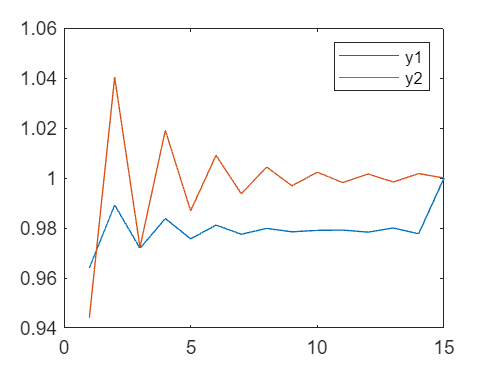

plot(X(2:4:end));;hold on;
plot(X(3:4:end));
legend('y1','y2')

## Con restricciones

Ades=zeros(0,N*(nx+nu));
bdes=zeros(0,1);
index_nuevo=1;
%y2<=1.02
Cx2=C(2,:)
for k=1:N
    Ades(index_nuevo,nx*(k-1)+(1:nx))=Cx2;
    bdes(index_nuevo)=1.02;
    index_nuevo=index_nuevo+1;
end
Cx2=-C(1,:)
for k=8:N
    Ades(index_nuevo,nx*(k-1)+(1:nx))=Cx2;
    bdes(index_nuevo)=-0.99;
    index_nuevo=index_nuevo+1;
end
%-y1<=-0.99 k>=N/2
z=quadprog(Qbig,q,Ades,bdes,Aeq,beq)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


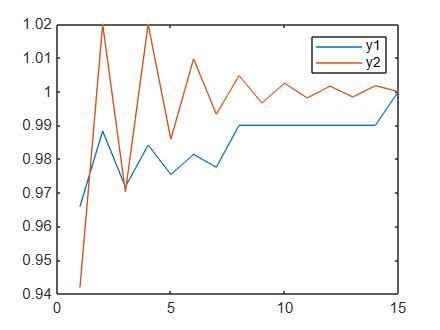

X=z(1:(nx*N));
U=z((nx*N)+(1:(nu*N)));
figure
plot(X(2:4:end));;hold on;
plot(X(3:4:end));
legend('y1','y2')


% Ades=[ze ze ze ze ze id zeB zeB zeB zeB;
%      ze ze ze ze ze zeB id zeB zeB zeB;
%      ze ze ze ze ze zeB zeB id zeB zeB;
%      ze ze ze ze ze zeB zeB zeB id zeB;
%      ze ze ze ze ze zeB zeB zeB zeB id;
%      Cx2 ze ze ze ze zeB zeB zeB zeB zeB;
%      ze Cx2 ze ze ze zeB zeB zeB zeB zeB;
%      ze ze Cx2 ze ze zeB zeB zeB zeB zeB;
%      ze ze ze Cx2 ze zeB zeB zeB zeB zeB;
%      ze ze ze ze Cx2 zeB zeB zeB zeB zeB;
%      Cx2min ze ze ze ze zeB zeB zeB zeB zeB;
%      ze Cx2min ze ze ze zeB zeB zeB zeB zeB;
%      ze ze Cx2min ze ze zeB zeB zeB zeB zeB;
%      ze ze ze Cx2min ze zeB zeB zeB zeB zeB;
%      ze ze ze ze Cx2min zeB zeB zeB zeB zeB;]
% bdes=[2.8*[1;1;1;1;1;]
%      4e-3*[1;1;1;1;1;]
%      2e-3*[1;1;1;1;1;]];
